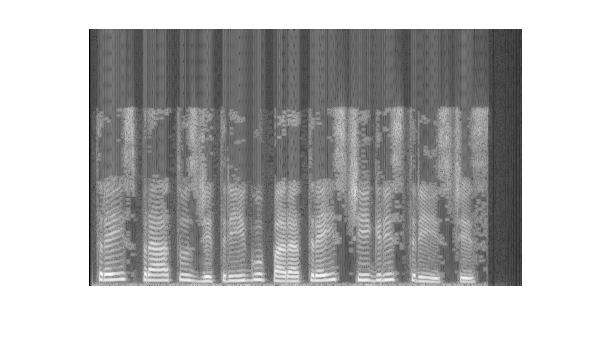

[amostras,freq_amostragem] = audioread("TigreTriste.wav");

amostras = amostras';
amostras = amostras / 10; % Diminuir amplitude
tam_jan = round(freq_amostragem/50);

X = spectrogram(amostras, tam_jan);

espectrograma = X / max(abs(X(:)));
espectrograma = flipud(espectrograma);

blocos = size(espectrograma, 2);
freq_pico = zeros(1, blocos);


for n = 1:blocos
  bloco_espectrograma = espectrograma(:, n);


  [~, pos_max] = max(bloco_espectrograma);
  freq_pico(n) = (pos_max - 1) * freq_amostragem / tam_jan;
end

imshow(abs(espectrograma).^0.1);